1) Find the digital frequency of a 20 Hz sinusoidal signal is sampled at 100 Hz

2) Find the order and cutoff frequency of a Butterworth digital lowpass filter with no more than 2dB attenuation below 2200 Hz and at least 35 dB attenuation at and beyond 2400 Hz. The sampling frequency is 6000 Hz.

Fs = 6000;          
Fn = Fs / 2;        
wp = 2200 / Fn;     
ws = 2400 / Fn;     
Rp = 2;             
Rs = 35;          

[N, wc] = buttord(wp, ws, Rp, Rs)

N = 14

wc = 0.7397

Design an 8-th order Butterworth lowpass digital filter with a cutoff frequency of 5 rad/s and sampling rate of 50 Hz.

[z, p, k] = buttap(8);              
[num, den] = zp2tf(z, p, k);        
wc = 5;                             
[num, den] = lp2lp(num, den, wc);   
Fs = 50;                            
[numd, dend] = bilinear(num, den, Fs);  

disp('numd ='), disp(numd')

numd =
   1.0e-08 *

    0.0030
    0.0242
    0.0847
    0.1693
    0.2116
    0.1693
    0.0847
    0.0242
    0.0030



disp('dend ='), disp(dend')

dend =
    1.0000
   -7.4879
   24.5453
  -46.0053
   53.9248
  -40.4765
   18.9996
   -5.0991
    0.5990




[Hd, wd] = freqz(numd, dend);
magd = abs(Hd);                     

subplot(2, 1, 1);
plot(wd / pi, magd); grid;
title('8-th order Lowpass Butterworth Digital Filter');
ylabel('Amplitude Response');
axis([0 0.2 0 1]);

subplot(2, 1, 2);
plot(wd / pi, angle(Hd)); grid;
ylabel('Phase Response');
xlabel('Frequency [in units of \pi]');
axis([0 0.2 -200 200]);

Design a 7-th order lowpass Butterworth filter having a cutoff frequency of 5 rad/s and Fs=20 Hz.

N = 7;               
Fs = 20;             
wc = 5;              
omegad = wc / (pi * Fs);  

[numd, dend] = butter(N, omegad);

[Hd, wd] = freqz(numd, dend);
magd = abs(Hd);      
phase = angle(Hd) * 180 / pi;  

subplot(2, 1, 1);
plot(wd / pi, magd); grid;
title('7-th order Lowpass Butterworth Digital Filter');
ylabel('Magnitude Response');

subplot(2, 1, 2);
plot(wd / pi, phase); grid;
ylabel('Phase Response');
xlabel('Frequency [in units of \pi]');

Design a 10-th order elliptic lowpass filter with a cutoff frequency of 300 Hz, 0.65 dB of ripple in the passband and a minimum stopband attenuation of 70 dB to be used with a signal that will be sampled at 6 kHz.

Fs = 6000; 
Rp = 0.65;  
Rs = 70;    
Fc = 300;   

[numd, dend] = ellip(10, Rp, Rs, 2 * Fc / Fs);

f = linspace(0, Fs / 2, 512);   
[H, f] = freqz(numd, dend, 512, Fs);  

mag = 20 * log10(abs(H));

plot(f, mag, 'LineWidth', 2);
grid on;
axis([0 Fs / 2 -90 10]);
xlabel('Frequency (Hz)');
ylabel('Magnitude response (dB)');
title('Frequency response of the 10th-order Elliptic Lowpass Filter');clear all;
Fs = 6000;  
Rp = 0.65;  
Rs = 70;    
Fc = 300;   

[numd, dend] = ellip(10, Rp, Rs, 2 * Fc / Fs);

f = linspace(0, Fs / 2, 512);   
[H, f] = freqz(numd, dend, 512, Fs);  

mag = 20 * log10(abs(H));

plot(f, mag, 'LineWidth', 2);
grid on;
axis([0 Fs / 2 -90 10]);
xlabel('Frequency (Hz)');
ylabel('Magnitude response (dB)');
title('Frequency response of the 10th-order Elliptic Lowpass Filter');

A sequence has 1.5 kHz sampling. Design an 10-th order Chebyshev Type I bandpass filter that has a bandwidth of 60 Hz centered at 400 Hz, with 0.4 dB of ripple in the passband. Plot the magnitude response between 100 Hz and 700 Hz, and the pole-zero diagram.

Fs = 1500;  
Rp = 0.4;   
Fc1 = 370; 
Fc2 = 430;  

Wn = [Fc1 Fc2] / (Fs / 2);

[b, a] = cheby1(10, Rp, Wn);

f = linspace(0, Fs / 2, 512);   
[H, f] = freqz(b, a, 512, Fs);  

subplot(2, 1, 1);
plot(f, abs(H), 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude response');
title('Frequency response of the 10th-order Chebyshev Type I Bandpass Filter');
xlim([100 700]);

subplot(2, 1, 2);
zplane(b, a);
title('Pole-Zero Plot');

Design a 8-th order IIR Chebyshev type I bandpass filter with cutoff frequencies at 500 Hz and 5000 Hz, 0.65 dB of ripple in the passband to be used with a signal that is sampled at 10kHz.

Fs=10000;
Fn=Fs/2;
w1=500/6000;
w2=5000/6000;
wc=[w1 w2];
order=8

order = 8

ripple=0.65;
[b, a]=cheby1(order, ripple,wc);
w=0:pi/99:99;
H=freqz(b,a,w);
mag=20*log10(abs(H));
phase=angle(H);
tol=0.95*pi;
phase=unwrap(phase,tol);
plot(mag,H)

title("Magnitude for plot IIR filter")
xlabel("Frequency (radians)")
ylabel("Magnitude (dB)")

Determine the impulse response and sketch the LTI filter described by the following difference equation

y[n] = x[n] - 3x[n-1] + 3x[n-2] - x[n-3]

a = [1];
b = [1 -3 3 -1];

imp = [1 zeros(1, 31)];

y = filter(b, a, imp);

stem(y);
title('Impulse Response of the LTI Filter');
xlabel('n (time index)');
ylabel('Amplitude');

An analog filter is described by its transfer function given by

Assume the sampling frequency of 15 Hz and a matching frequency of 1.5 Hz. Use the bilinear transformation method to find a digital filter equivalent.

num = [1 0.1];                   
den = [1 0.2 9];                 

Fs = 15;                         
matching_freq = 1.5;             
[numd, dend] = bilinear(num, den, Fs, matching_freq);

[Ha, wa] = freqs(num, den);

[Hd, Fd] = freqz(numd, dend, 256, 'whole', Fs);

plot(wa/(2*pi), 20*log10(abs(Ha/Ha(1))), 'b', 'LineWidth', 3);
hold on;
plot(Fd, 20*log10(abs(Hd/Hd(1))), 'k', 'LineWidth', 3);
hold off;

xlabel('Frequency (Hz)');
ylabel('Magnitude response (dB)');
title('Frequency response: Analog vs Digital (Bilinear Transformation)');
legend('Analog', 'Digital: Bilinear');

An analog filter is specified by its transfer function given by

Use the impulse invariance method to design its digital counterpart. Compare the analog filter to two versions of the digital filter; one with a sampling frequency of 30 Hz the other with a sampling frequency of 70 Hz.

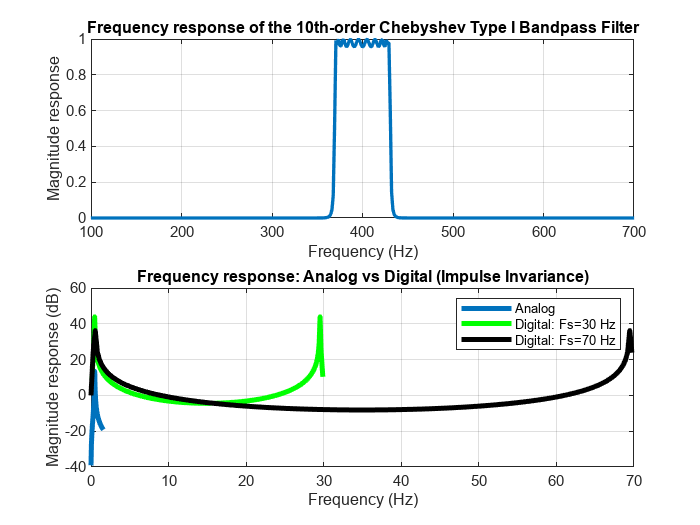

num = [1 0.1];                   
den = [1 0.2 9];                 
Fs1 = 30;                        
Fs2 = 70;                        
[numd1, dend1] = impinvar(num, den, Fs1);
[numd2, dend2] = impinvar(num, den, Fs2);
[H, w] = freqs(num, den);
[Hd1, Fd1] = freqz(numd1, dend1, 256, 'whole', Fs1);
[Hd2, Fd2] = freqz(numd2, dend2, 256, 'whole', Fs2);
plot(w/(2*pi), 20*log10(abs(H)), 'LineWidth', 3); grid on;
hold on;
plot(Fd1, 20*log10(abs(Hd1/Hd1(1))), 'g', 'LineWidth', 3);
plot(Fd2, 20*log10(abs(Hd2/Hd2(1))), 'k', 'LineWidth', 3);
hold off;
legend('Analog', 'Digital: Fs=30 Hz', 'Digital: Fs=70 Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude response (dB)');
title('Frequency response: Analog vs Digital (Impulse Invariance)');

Design a Butterworth digital lowpass filter with no more than 2 dB attenuation below 900 Hz and at least 50 dB attenuation at and beyond 4000 Hz. The sampling frequency is 12000 Hz. Find the coefficients of second-order sections

Fs = 12000;               
Fn = Fs / 2;              
wp = 900 / Fn;            
ws = 4000 / Fn;           
Rp = 2;                   
Rs = 50;                  
[N, Wn] = buttord(wp, ws, Rp, Rs);
[B, A] = butter(N, Wn);
[z, p, k] = tf2zp(B, A);
sos = zp2sos(z, p, k);
disp('Second-order sections (sos):');

Second-order sections (sos):


disp(sos);

    0.0100    0.0199    0.0100    1.0000   -0.8625    0.2126
    1.0000    2.0000    1.0000    1.0000   -1.1211    0.5761



fvtool(sos, 'Analysis', 'freq');